# 倒立摆系统建模分析

## 1 系统建模

### 1.1简化与假设

- 不考虑杆子转动阻尼以及车轮与地面摩擦等等外力因素。

- 杆子偏离平衡位置角度极小，可做小角近似。

### 1.2 参数定义

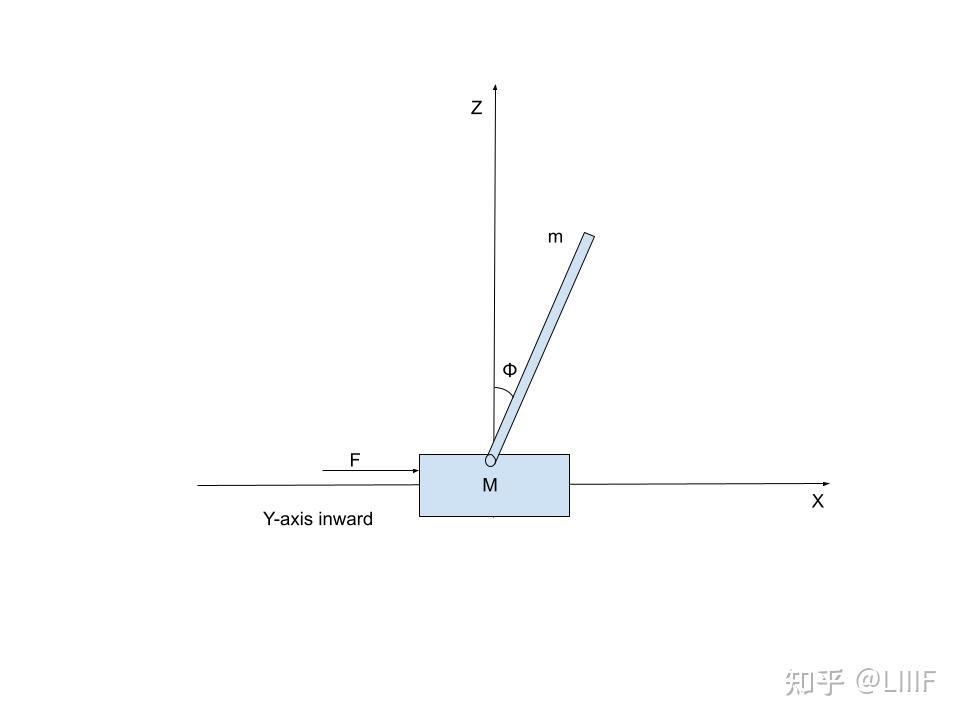

M：车身质量

m：杆子质量

b：车身与地面阻尼系数

I：杆子绕质心轴的转动惯量

g：重力加速度

L：杆子质心到转点的距离


$$q=\left(M+m\right)*\left(I+m*L^2 \right)-\left(m*L{\left.\right)}^2 \right.$$



$$p=I*\left(m+M\right)+M*m*L^2$$


$\phi$：杆子偏离平衡位置的角度

x：车身偏离 $x=0$的距离

Inpend = struct;
g = sym("g");

Inpend.M = sym("M");
Inpend.m = sym("m");
Inpend.b = sym("b");
Inpend.I = sym("I");
Inpend.L = sym("L");
Inpend.q = (Inpend.M + Inpend.m)*(Inpend.I+Inpend.m*Inpend.L^2)-(Inpend.m*Inpend.L)^2;
Inpend.p = Inpend.I*(Inpend.m+Inpend.M)+Inpend.M*Inpend.m*Inpend.L^2;

## 2 状态空间模型

状态空间方程满足如下形式：


$$\left\lbrace \begin{array}{ll}
\dot{\mathit{\mathbf{x}}\;} =A\;\mathit{\mathbf{x}}+B\;\mathit{\mathbf{u}} & \\
\mathit{\mathbf{y}}=C\;\mathit{\mathbf{x}}+D\;\mathit{\mathbf{u}} & 
\end{array}\right.$$


我们选取状态向量：


$$\mathbf{x} = 
\left[\matrix{
x & \dot{x} & \phi & \dot{\phi}
}\right]^{\top}$$


控制向量：


$$\mathbf{x} = 
\left[\matrix{
f
}\right]^{\top}$$


输出向量：


$$\mathbf{y} = 
\mathbf{x}$$


通过计出状态空间方程：


$$A = 
\left[\matrix{
0 & 1 & 0 & 0  \cr
0 & -\frac{(mL^{2} + I)b}{p} & -\frac{gm^{2}L^{2}}{p} & 0\cr
0 & 0 & 0 & 1 \cr
0 & -\frac{mLb}{p} & \frac{mgL(M + m)}{p} & 0 \cr
}\right]$$



$$B = 
\left[\matrix{
0  \cr
\frac{mL^{2} + I}{p} \cr
0 \cr
-\frac{mL}{p}
}\right]$$



$$C = Id_4$$



$$D = 0
$$


Inpend.A = sym(zeros(4,4));
Inpend.B = sym(zeros(4,1));
% Inpend.C = sym(eye(4));
% Inpend.D = sym(zeros(4,1));
Inpend.C = [1  0  0  0
     0  0  1  0];
Inpend.D = [0; 0];

Inpend.A(1,2) = 1;
Inpend.A(3,4) = 1;
Inpend.A(2,2) = -((Inpend.I + Inpend.m*Inpend.L^2)*Inpend.b)/Inpend.p;
Inpend.A(2,3) = -(g*Inpend.m^2*Inpend.L^2)/Inpend.p;
Inpend.A(4,2) = -(Inpend.b*Inpend.m*Inpend.L)/Inpend.p;
Inpend.A(4,3) = (Inpend.m*Inpend.L*g*(Inpend.M + Inpend.m))/Inpend.p;

Inpend.B(2) = (Inpend.m*Inpend.L^2 + Inpend.I)/Inpend.p;
Inpend.B(4) = -(Inpend.m*Inpend.L)/Inpend.p

Inpend = 包含以下字段的 struct :
    M: M
    m: m
    b: b
    I: I
    L: L
    q: (M + m)*(m*L^2 + I) - L^2*m^2
    p: M*m*L^2 + I*(M + m)
    A: [4×4 sym]
    B: [4×1 sym]
    C: [2×4 double]
    D: [2×1 double]
